# Portfolio Optimization Against a Benchmark

This example shows how to perform portfolio optimization using the [Portfolio](docid:finance_ug.buk6uyz-1) object in Financial Toolbox™. 

This example, in particular, demonstrates optimizing a portfolio to maximize the information ratio relative to a market benchmark. Specifically, financial data contained in a [table](docid:matlab_ref.btw1ta8-1) is read into MATLAB® and visualizations (at both daily and annual levels) are performed.  A [Portfolio](docid:finance_ug.buk6uyz-1) object is created with the market data using an active daily return for each asset. Using functions supporting a [Portfolio](docid:finance_ug.buk6uyz-1) object, the efficient frontier is calculated directly. Then, a customized optimization problem is solved to find the asset allocation with the maximized information ratio.

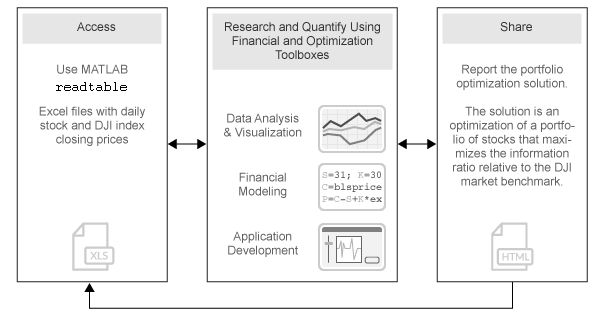

## **Import Historical Data Using MATLAB®**

Import historical prices for the asset universe and the Dow Jones Industrial Average (DJI) market benchmark. The data is imported into a [table](docid:matlab_ref.btw1ta8-1) from a Microsoft® Excel® spreadsheet using the MATLAB® [readtable](docid:matlab_ref.btx_238-1) function.

data = readtable('dowPortfolio.xlsx');
head(data, 10)

Separate the asset names, asset prices, and DJI benchmark prices from the table. The visualization shows the evolution of all the asset prices normalized to start at unity, that is accumulative returns.

benchPrice = data.DJI;
assetNames = data.Properties.VariableNames(3:2:end); % using half of the assets for display
assetPrice = data(:,assetNames).Variables;

assetP = assetPrice./assetPrice(1, :);  
benchmarkP = benchPrice / benchPrice(1);

figure;
plot(data.Dates,assetP);
hold on;
plot(data.Dates,benchmarkP,'LineWidth',3,'Color','k');
hold off;
xlabel('Date');
ylabel('Normalized Price');
title('Normalized Asset Prices and Benchmark');
grid on;

The bold line indicates the DJIA market benchmark.

## **Compute Returns and Risk-Adjusted Returns**

Calculate the return series from the price series and compute the asset moments (historical returns and standard deviations). The visualization shows a scatter plot of the risk-return characteristics of all the assets and the DJI market benchmark. 

benchReturn = tick2ret(benchPrice);
assetReturn = tick2ret(assetPrice);

benchRetn = mean(benchReturn);
benchRisk =  std(benchReturn);
assetRetn = mean(assetReturn);
assetRisk =  std(assetReturn);

Calculate historical statistics and plot the annual risk-return. Note that the plot is at the annual level, therefore scaling is performed on the daily returns.

scale = 252;

assetRiskR = sqrt(scale) * assetRisk;
benchRiskR = sqrt(scale) * benchRisk;
assetReturnR = scale * assetRetn;
benchReturnR = scale * benchRetn;

figure;
scatter(assetRiskR, assetReturnR, 6, 'm', 'Filled');
hold on
scatter(benchRiskR, benchReturnR, 6, 'g', 'Filled');
for k = 1:length(assetNames)
    text(assetRiskR(k) + 0.005, assetReturnR(k), assetNames{k}, 'FontSize', 8);
end
text(benchRiskR + 0.005, benchReturnR, 'Benchmark', 'Fontsize', 8);
hold off;

xlabel('Risk (Std Dev of Return)');
ylabel('Expected Annual Return');
grid on;

## **Set Up a Portfolio Optimization**

Set up a portfolio optimization problem by populating the object using [Portfolio](docid:finance_ug.buk6uyz-1). Because the goal is to optimize portfolio allocation against a benchmark, the active return of each asset is computed and used in the [Portfolio](docid:finance_ug.buk6uyz-1) object. In this example, the expected returns and covariances of the assets in the portfolio are set to their historical values.

p = Portfolio('AssetList',assetNames);

Set up default portfolio constraints (all weights sum to `1`, no shorting, and 100% investment in risky assets).

p = setDefaultConstraints(p);

Add asset returns and covariance to the [Portfolio](docid:finance_ug.buk6uyz-1) object.

activReturn = assetReturn - benchReturn;
pAct = estimateAssetMoments(p,activReturn,'missingdata',false)

## **Compute the Efficient Frontier Using the **`Portfolio`** Object**

Compute the mean-variance efficient frontier of 20 optimal portfolios. Visualize the frontier over the risk-return characteristics of the individual assets. Furthermore, calculate and visualize the information ratio for each portfolio along the frontier.

pwgtAct = estimateFrontier(pAct, 20); % Estimate the weights.
[portRiskAct, portRetnAct] = estimatePortMoments(pAct, pwgtAct); % Get the risk and return.

% Extract the asset moments and names.
[assetActRetnDaily, assetActCovarDaily] = getAssetMoments(pAct);
assetActRiskDaily = sqrt(diag(assetActCovarDaily));
assetNames = pAct.AssetList;

% Rescale.
assetActRiskAnnual = sqrt(scale) * assetActRiskDaily;
portRiskAnnual  = sqrt(scale) *  portRiskAct;
assetActRetnAnnual = scale * assetActRetnDaily;
portRetnAnnual = scale *  portRetnAct;

figure;
subplot(2,1,1);
plot(portRiskAnnual, portRetnAnnual, 'bo-', 'MarkerFaceColor', 'b');
hold on;

scatter(assetActRiskAnnual, assetActRetnAnnual, 12, 'm', 'Filled');
hold on;
for k = 1:length(assetNames)
    text(assetActRiskAnnual(k) + 0.005, assetActRetnAnnual(k), assetNames{k}, 'FontSize', 8);
end

hold off;

xlabel('Risk (Std Dev of Active Return)');
ylabel('Expected Active Return');
grid on;

subplot(2,1,2);
plot(portRiskAnnual, portRetnAnnual./portRiskAnnual, 'bo-', 'MarkerFaceColor', 'b');
xlabel('Risk (Std Dev of Active Return)');
ylabel('Information Ratio');
grid on;

## **Perform Information Ratio Maximization Using Optimization Toolbox™**

Run a hybrid optimization to find the portfolio along the frontier with the maximum information ratio. The information ratio is the ratio of relative return to relative risk (known as "tracking error"). Whereas the Sharpe ratio looks at returns relative to a riskless asset, the information ratio is based on returns relative to a risky benchmark, in this case the DJI benchmark. This is done by running an optimization that finds the optimal return constraint for which the portfolio optimization problem returns the maximum information ratio portfolio. The portfolio optimization functions are called from an objective function `infoRatioTargetReturn` that is optimized by the Optimization Toolbox™ function [fminbnd](docid:optim_ug.bu_pfzo). The local function `infoRatioTargetReturn` calculates a minimum (active) risk portfolio given a target active return. 

The `infoRatioTargetReturn` local function is called as an objective function in an optimization routine ([fminbnd](docid:optim_ug.bu_pfzo)) that seeks to find the target return that maximizes the information ratio and minimizes a negative information ratio.

objFun = @(targetReturn) -infoRatioTargetReturn(targetReturn,pAct);
options = optimset('TolX',1.0e-8);
[optPortRetn, ~, exitflag] = fminbnd(objFun,min(portRetnAct),max(portRetnAct),options);

Get weights, information ratio, and risk return for the optimal portfolio.

[optInfoRatio,optWts] = infoRatioTargetReturn(optPortRetn,pAct);
optPortRisk = estimatePortRisk(pAct,optWts) 

## **Plot the Optimal Portfolio**

Verify that the portfolio found is indeed the maximum information-ratio portfolio.

% Rescale.
optPortRiskAnnual = sqrt(scale) * optPortRisk;
optPortReturnAnnual = scale * optPortRetn;

figure;
subplot(2,1,1);

scatter(assetActRiskAnnual, assetActRetnAnnual, 6, 'm', 'Filled');
hold on
for k = 1:length(assetNames)
    text(assetActRiskAnnual(k) + 0.005,assetActRetnAnnual(k),assetNames{k},'FontSize',8);
end
plot(portRiskAnnual,portRetnAnnual,'bo-','MarkerSize',4,'MarkerFaceColor','b');
plot(optPortRiskAnnual,optPortReturnAnnual,'ro-','MarkerFaceColor','r');
hold off;

xlabel('Risk (Std Dev of Active Return)');
ylabel('Expected Active Return');
grid on;

subplot(2,1,2);
plot(portRiskAnnual,portRetnAnnual./portRiskAnnual,'bo-','MarkerSize',4,'MarkerFaceColor','b');
hold on
plot(optPortRiskAnnual,optPortReturnAnnual./optPortRiskAnnual,'ro-','MarkerFaceColor','r');
hold off;

xlabel('Risk (Std Dev of Active Return)');
ylabel('Information Ratio');
title('Information Ratio with Optimal Portfolio');
grid on;

## **Display the Portfolio Optimization Solution**

Display the portfolio optimization solution.

assetIndx = optWts > .001;
results = table(assetNames(assetIndx)', optWts(assetIndx)*100, 'VariableNames',{'Asset', 'Weight'});
disp('Maximum Information Ratio Portfolio:')
disp(results)
fprintf('Active return for Max. Info Ratio portfolio is %0.2f%%\n', optPortRetn*25200);
fprintf('Tracking error for Max. Info Ratio portfolio is %0.2f%%\n', optPortRisk*sqrt(252)*100);

## **Local Function**

function [infoRatio,wts] = infoRatioTargetReturn(targetReturn,portObj)
% Calculate information ratio for a target-return portfolio along the
% efficient frontier.
wts = estimateFrontierByReturn(portObj,targetReturn);
portRiskAct = estimatePortRisk(portObj,wts);
infoRatio = targetReturn/portRiskAct;
end

*Copyright 2012 The MathWorks, Inc.*